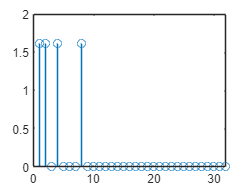

clear
% Заданные спектральные компоненты (амплитуда и фаза)
N = 32; % Размер сигнала
amplitude = zeros(1,N);

%amplitude(1) = sqrt(2) + 1j*pi/4; %00
%amplitude(2) = sqrt(2) - 1j*pi/4; %01
%amplitude(4) = -sqrt(2) - 1j*pi/4;%10
%amplitude(8) = -sqrt(2) + 1j*pi/4;%11

%amplitude(1) = 1 + 1j*pi/4; %11
%amplitude(2) = 3 + 1j*pi/4; %00
%amplitude(4) = 5 + 1j*pi/4; %01
%amplitude(8) = 2 + 1j*pi/4; %00
%0x30 0011 0000
%0x31 0011 0001
amplitude(1) = sqrt(2) + 1j*pi/4; %00
amplitude(2) = sqrt(2) + 1j*pi/4; %00
amplitude(4) = sqrt(2) + 1j*pi/4; %00
amplitude(8) = sqrt(2) + 1j*pi/4; %00

ts = 1/length(amplitude);
t = 0:ts:1-ts;    
f = (1:length(amplitude))*N/length(amplitude);        % Frequency vector


stem(f, abs(amplitude));

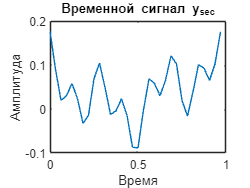


y_sec = ifft(amplitude);
figure;
plot(t, real(y_sec));
xlabel('Время');
ylabel('Амплитуда');
title('Временной сигнал y_{sec}');

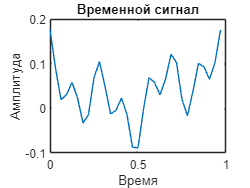


y = fft(amplitude);
y_reverse = y;
y_reverse(2:end) = y(end:-1:2);
y_reverse = y_reverse ./ N;
figure;
plot(t, real(y_reverse));
xlabel('Время');
ylabel('Амплитуда');
title('Временной сигнал');

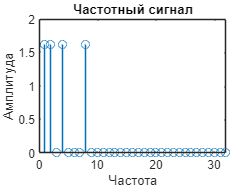


fft_check = fft(y_reverse);
figure;
stem(f, abs(fft_check));
xlabel('Частота');
ylabel('Амплитуда');
title('Частотный сигнал');